clc
clear

数据

filename ='1module_test_27.5v_single_2';
filename ='..\..\..\data_Newsystem\2module_20180717\2module_Source_3';
% filename ='1module_test_27.5v_sum1024_all_4';

fid=fopen([filename '.dat'],'rb');

raw = fread(fid,'uint8');
fclose(fid);
raw = raw(4001:end);
data = reshape(raw,4,length(raw)/4)';
clear raw

筛选完整的车

%找到所有完整数据列车的车头train_head_index
train_head_8bit = 254;
p1 = find(data(:,4) == train_head_8bit);
p2 = p1 + 1;
if  max(p2) > length(data)
    p2 = p2(1:end - 1);
end
train_head_index = p2((data(p2,4) == train_head_8bit) & (data(p2,1) == 0) & (data(p2,2) == 0) &(data(p2,3) == 0));
clear p1 p2 train_head_8bit;
train_len = diff(train_head_index);
%列车数
train_cnt = length(train_head_index);

%提取出所有完整的车的数据，存在data
c_train_len = 276;
p1 = find(train_len == c_train_len);
complet_train_head_index = train_head_index(p1) - 1;  %%好像不用减1
clear p1 train_len;
%完整列车数
complet_train_cnt = length(complet_train_head_index);

train_data_complete = zeros(complet_train_cnt * c_train_len,4);
head_index = 1 : c_train_len : c_train_len * complet_train_cnt;
head_index = head_index';
for i = 0 : 1 : c_train_len - 1
    train_data_complete(head_index + i,:) = data(complet_train_head_index + i,:);
end
clear data;
data = train_data_complete;
clear train_data_complete complet_train_head_index head_index;

提取所有module_num车厢的数据

module_num=0;
%提取module_num车厢数据
CoachSelected=find((data(:,1)==0) & (data(:,3)==module_num) & (data(:,4)==240));
for i=1:1:16
    CoachData(:,4*i-3:4*i)=data(CoachSelected(:)-17+i,:);
end
CoachData=reshape(CoachData',4,length(CoachSelected)*16)';
clear CoachData1

提取所有有效数据

dataEnd=CoachData(4:4:length(CoachData),:);
invalid_dataEnd_index=find((dataEnd(:,2)==128) & (dataEnd(:,3)==128) & (dataEnd(:,4)==128));
clear dataEnd 
for i=1:1:4
    CoachData(invalid_dataEnd_index*4-4+i,:)=repmat([255 255 255 255],length(invalid_dataEnd_index),1);
end
clear invalid_dataEnd_index
dataDelete=find(CoachData(:,1)==255 & CoachData(:,2)==255 & CoachData(:,3)==255 & CoachData(:,4)==255);
CoachData(dataDelete,:)=[];
clear dataDelete

处理能量

CoachData1=reshape(CoachData',16,length(CoachData)/4)';
% clear CoachData
CoachData1((CoachData1(:,16)~=128),:)=[];

各channel能量

for i=1:5
    eng(:,2*i-1)=rem(CoachData1(:,3*i-1),16)*256 + CoachData1(:,3*i-2);
    if i<5
        eng(:,2*i)=floor(CoachData1(:,3*i-1)/16) + CoachData1(:,3*i)*16;
    else
        eng(:,2*i)=CoachData1(:,3*i);
    end
end
clear CoachData1
save([filename '_eng.mat'],'eng');

channel plot

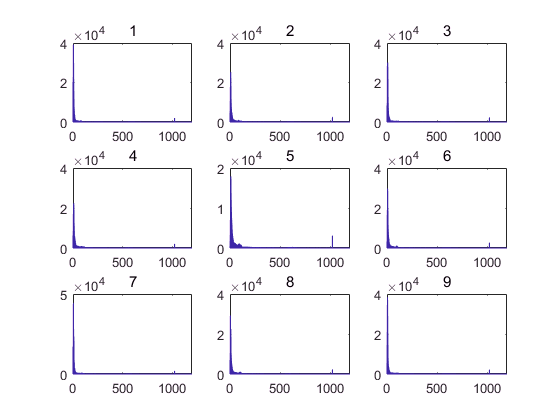

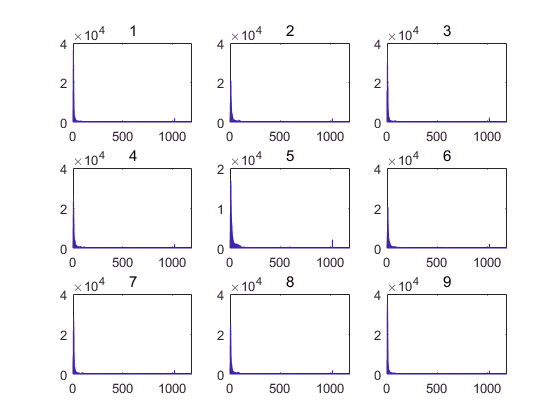

for evt_num=0:1
    index=(eng(:,10)==evt_num);
    figure;
    for i=1:9
        subplot(3,3,i);hist(eng(index,i),0:1:2000);xlim([0 1200]);title(i);
    end
end

sum eng plot

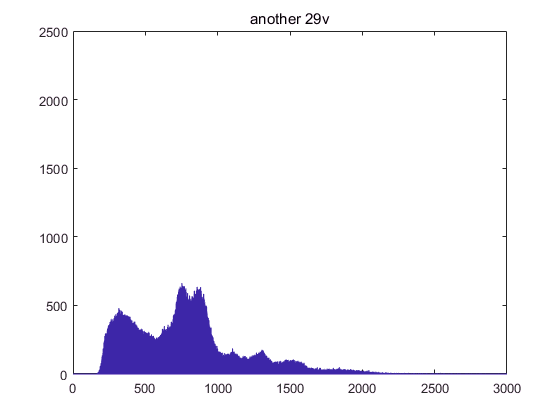

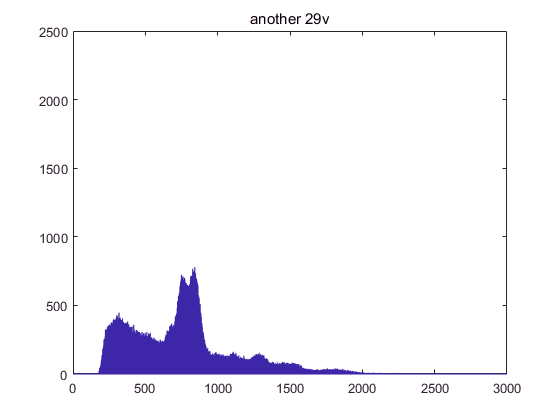

for evt_num=0:1
    index=(eng(:,10)==evt_num);
    figure;
    eng_total=sum(eng(index,1:9),2);
    hist(eng_total,0:1:9000);xlim([0 3000]);ylim([0 2500]);title('another 29v');
end

Decoding3mmWith6mmSiPM

引用了已清除的变量 eng。

出错 Decoding3mmWith6mmSiPM (line 9)
    index=(eng(:,10)==evt_num);